# Generate and Displace Rectangular Pulse

Generate 200 ms of a rectangular pulse with a sample rate of 10 kHz and a width of 20 ms.

fs = 10e3;
t = -0.1:1/fs:0.1;

w = 20e-3;

x = rectpuls(t,w);

Generate two copies of the same pulse:

- One displaced 45 ms into the past.

tpast = -45e-3;
xpast = rectpuls(t-tpast,w);

- One displaced 60 ms into the future and half as wide.

tfutr = 60e-3;
xfutr = rectpuls(t-tfutr,w/2);

Plot the original pulse and the two copies on the same axes.

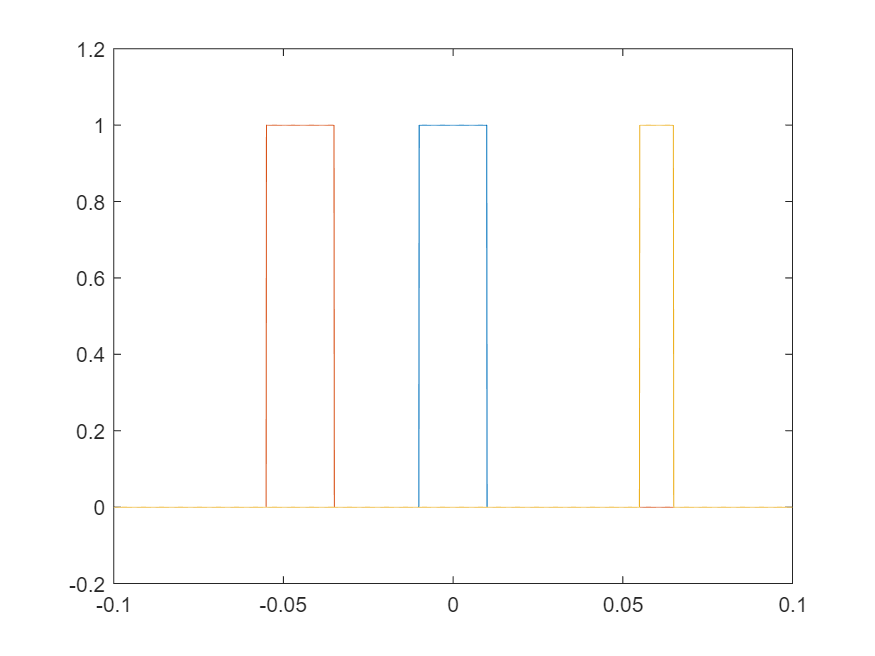

plot(t,x,t,xpast,t,xfutr)
ylim([-0.2 1.2])

*Copyright 2015 The MathWorks, Inc.*